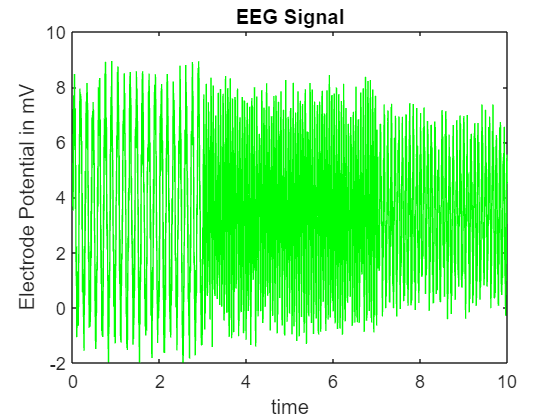

clear all;
close all;
clc;
% Load EEG data from .mat file
data=load("F:\IITM\Physiological measurements lab\EEGRAW.mat");
my_data=data.AM23M025;
time=(1:length(my_data))/250;
% Example: Bandpass filter between 1-30 Hz
figure();
plot(time,my_data,Color= "green");
title('EEG Signal');
ylabel('Electrode Potential in mV');
xlabel('time');

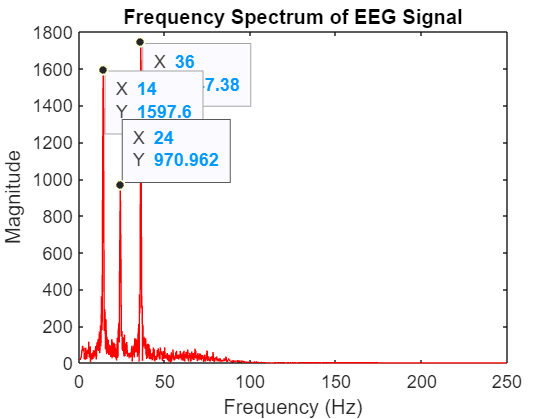

 
%sampling rate is 250 Hz
low_freq = 1;   % Set your desired low cutoff frequency in Hz
high_freq = 40;  % Set your desired high cutoff frequency in Hz
sampling_rate=250;
% Design a bandpass filter
[b, a] = butter(4, [low_freq, high_freq]/(sampling_rate/2), 'bandpass');
 
% Apply the bandpass filter
eeg_data_filtered = filtfilt(b, a, my_data);
% Example: Calculate FFT for each epoch
fft_data = fft(eeg_data_filtered);
% Example: Find peaks in the FFT
fft_result = fft_data(1:length(fft_data)/2); % Keep only the positive frequencies
% Calculate the frequency axis
% Calculate corresponding frequencies
frequencies = (0:length(fft_result)-1)*(sampling_rate/length(fft_result));
 
% Plot the spectrum
figure;
plot(frequencies, abs(fft_result), Color='red');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of EEG Signal');

% Identify SSVEP frequencies
% You may need to set a threshold or use peak detection to identify SSVEP frequencies
 
% Example: Assume SSVEPs occur between 5 and 20 Hz
ssvep_min_freq = 5;
ssvep_max_freq = 20;
ssvep_indices = find(frequencies >= ssvep_min_freq & frequencies <= ssvep_max_freq);
ssvep_magnitudes = abs(fft_result(ssvep_indices));
 
% Identify the dominant SSVEP frequency
[max_magnitude, max_index] = max(ssvep_magnitudes);
dominant_ssvep_frequency = frequencies(ssvep_indices(max_index));
 
fprintf('Dominant SSVEP Frequency: %.2f Hz\n', dominant_ssvep_frequency);

Dominant SSVEP Frequency: 14.00 Hz
